# **Detecția liniilor folosind transformata Hough**

## **Formularea problemei**

- **scop: găsirea unei metode generale care să returneze cât mai exact muchiile dintr-o imagine**

###    1. Transformata Hough

- dorim să găsim linii drepte

- varianta clasică: testăm toate punctele apoi verficăm și vecinătățile acelor puncte => restrictiv computațional

- **varianta transformatei Hough: consider puncte în spațiul parametrilor sub formă de linii, iar dacă acolo liniile se intersecteaza atunci punctele se regăsesc pe o dreaptă;**

- **    => cu cât sunt mai mule intersecții, cu atât mai multe puncte ce se regăsesc pe aceeași dreaptă**

            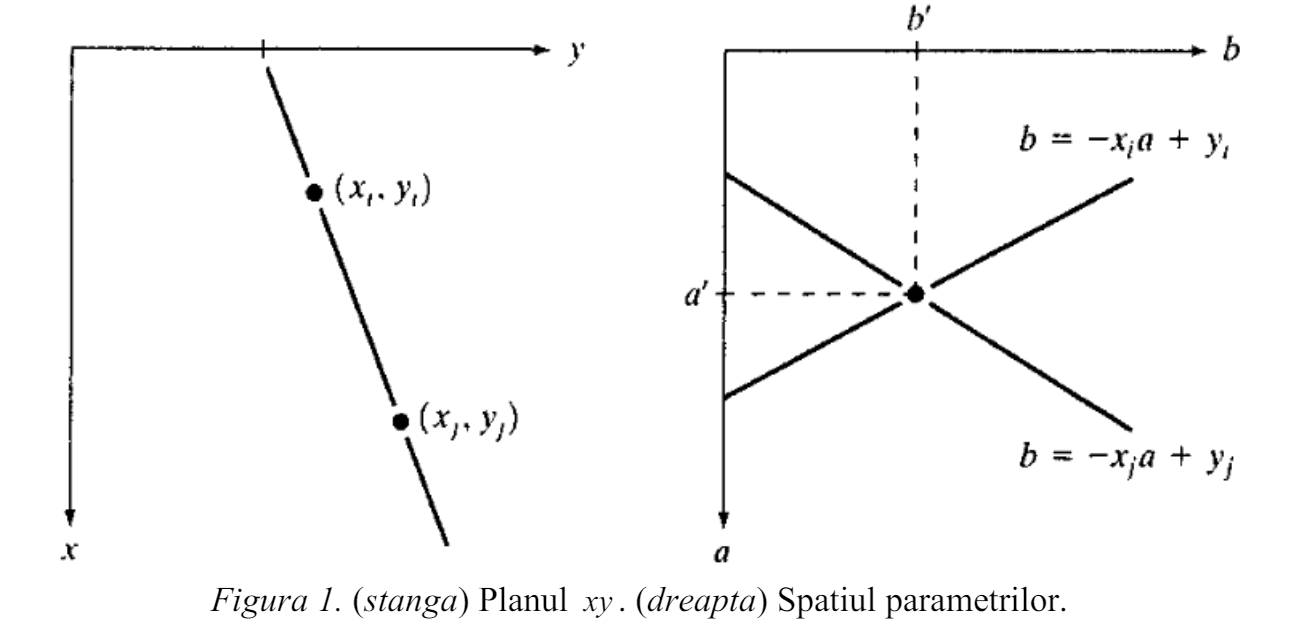

- o posibilă problemă poate apărea prin faptul că panta liniei **a **tinde spre infinit cu cât ne apropiem mai mult de direcția verticală => utilizăm **coordonate polare**

- **    => **se păstrează ideea că **intersecția a doua sau mai multe familii de sinusoide** corespunde unei **linii în planul original cartezian**

- **    => **mult mai usor de folosit computațional datorită **divizării spațiului în celule de acumulare, **care arată în final **câte puncte din planul xy se află pe o linie definită în planul parametrilor**

            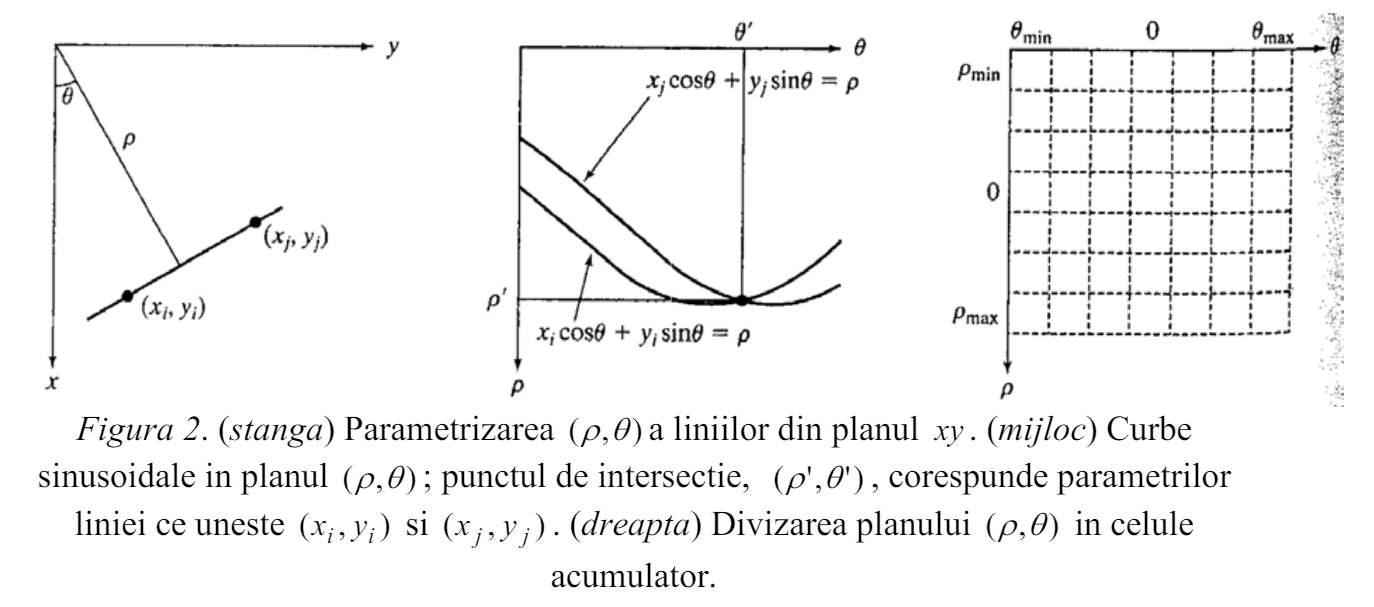

#### Matlab Function: hough()

% help hough

###    2. Detecția vârfurilor în spațiul Hough

- dorim să găsim linii drepte pe baza valorilor maxime din spațiul parametrilor

- strategie de detecție, suprimare în vecinătate și repetare până la atingerea unui prag

#### Matlab Function: houghpeaks()

% help houghpeaks

###    3. Detecția și conectarea liniilor folosind transformata Hough

- odată ce am găsit vârfurile, ne concentrăm pe determinarea existenței segmentelor dintre acele vârfuri, alături de pixelii care au contribuit la acel vârf.

- se aplică o strategie simplă de determinare a tuturor pixelilor de pe linie, trecând peste posibilele mici goluri

#### Matlab Function: houghlines()

% help houghlines

## Aplicații

### Exercițiul 1

% read image
i1 = imread('Images/building.tif');
% show the image
subplot(3, 2, 1);
imshow(i1); title('Imagine initiala');
is = edge(i1,'sobel');
ip = edge(i1,'prewitt');
ir = edge(i1,'roberts');
ic = edge(i1,'canny');
il = edge(i1,'log');
% valori implicite
subplot(3,2,2)
imshow(is);title('Muchii detectate cu Sobel');
subplot(3,2,3)
imshow(ip);title('Muchii detectate cu Prewitt');
subplot(3,2,4)
imshow(ir);title('Muchii detectate cu Roberts');
subplot(3,2,5)
imshow(ic);title('Muchii detectate cu Canny');
subplot(3,2,6)
imshow(il);title('Muchii detectate cu LoG');

### Exercițiul 2

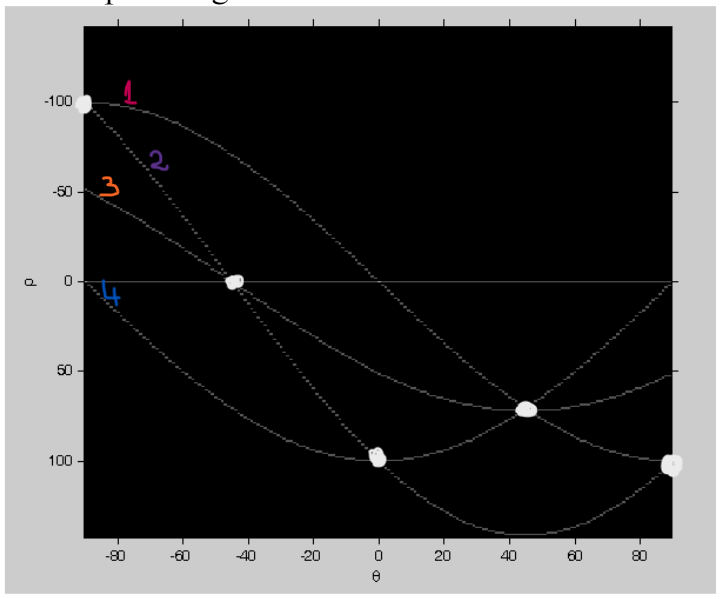

### Exercițiul 3

img = imread('Images/L10_image_03.png');
[h, t, r] = hough(img);
figure();
plotHoughCell(img, h, 700, 110);

### Exercițiul 4

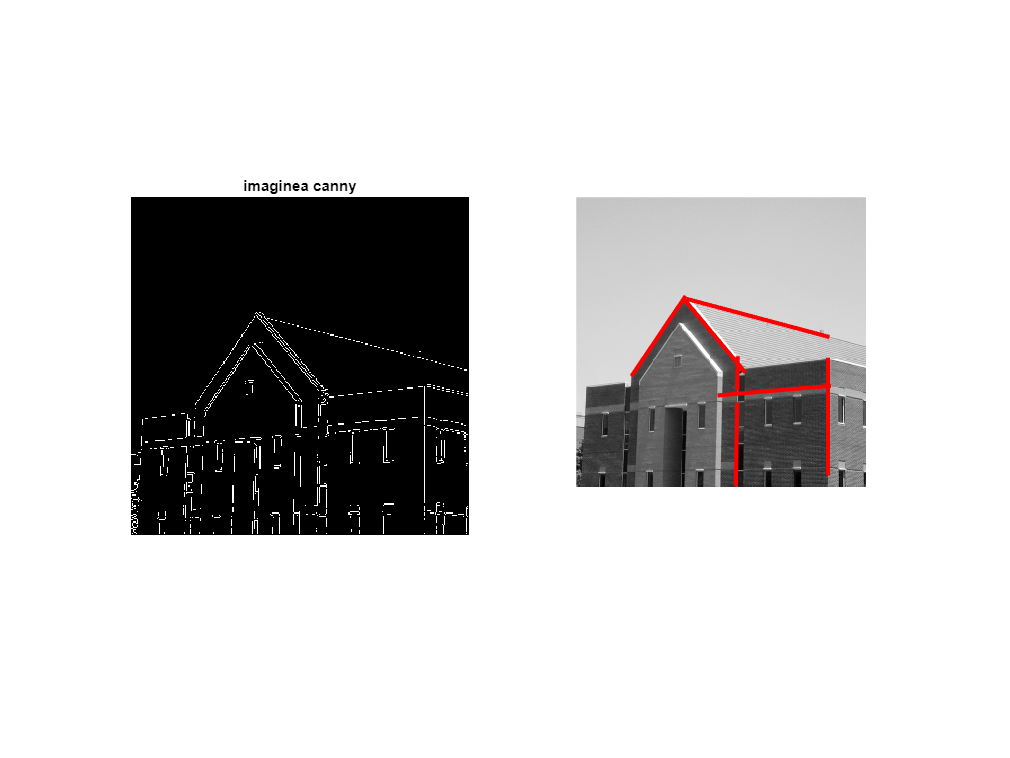

%% P4
im1 = imread('Images/building.tif');
im1 = im2gray(im1);
imp = edge(im1,'canny',0.2);
subplot(1,2,1)
imshow(imp);
title('imaginea canny');
% [H,theta,Ro]=hough(imp,'RhoResolution',0.5,'Theta',-90:0.5:89.5);
[H,theta,Ro] = hough(imp);
% V=houghpeaks(H,2,'threshold',ceil(0.3*max(H(:))));
V=houghpeaks(H,6);
% Lines=houghlines(imp,theta,Ro,V,'FillGap',10,'MinLength',25);
Lines = houghlines(imp,theta,Ro,V);
subplot(1,2,2)
hold on
imshow(im1);
for i=1:length(Lines)
    im = [Lines(i).point1; Lines(i).point2];
    plot(im(:,1),im(:,2),'LineWidth',3,'Color','red');
end

### Partea a 2-a

im1 = imread('Images/L10_image_04.png');  %de modificat
gray = rgb2gray(im1);
[rows, columns] = size(gray);
roi = gray(floor(rows/2):end, :);

% gaussian blur - optional;
blurred = imgaussfilt(roi, 2);

% edge detection using preffered method
edges = edge(blurred, 'canny');

% Hough Transform
[H, theta, rho] = hough(edges);
peaks = houghpeaks(H, 5, 'threshold', ceil(0.5*max(H(:))));
lines = houghlines(edges, theta, rho, peaks, 'FillGap', 50, 'MinLength', 100);

% Plot pe imaginea originala
figure, imshow(im1), hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];

    % un filtru pentru liniile orizontale (nu ar trebui sa fie benzi de
    % circulatie..
    angle = atan2(xy(2,2) - xy(1,2), xy(2,1) - xy(1,1)) * 180 / pi;
    if abs(angle) < 85 && abs(angle) > 30 % valori euristice

        % ajustarea coordonatelor liniilor pe coordonatele din imaginea originala
        xy(:,2) = xy(:,2) + floor(rows/2);

        % plotare linii pe imaginea originala
        plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');

        % plotare inceput si sfarsit linii - optional
        plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'yellow');
        plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
    end
end
hold off